# State Management in Transceiver Toolbox

In this section, we will look at how the tranceiver toolbox system objects have been designed to interact with the device. In other words, we discuss how the system objects set up hardware for transmitting and capturing streaming data to and from the device. Importantly, we will understand how various attributes are set and at which point during program execution, the updates to system object properties get translated to attribute changes in the hardware itself. 

## Life Cycle of a Transceiver Toolbox System Object

Let us consider the example of a Pluto receiver system object. Let us update the URI and capture a buffer of samples. 

dbclear all;
clear all;
plutoRx = adi.Pluto.Rx('uri','ip:pluto.local');
y = plutoRx();

Notice that you can change certain properties whenever you desire and recapture a buffer of samples as shown below. 

plutoRx.CenterFrequency = 2.2e9;
[~, cmdout] = system('iio_attr --uri ip:pluto.local -c ad9361-phy altvoltage0 frequency'); 
y = plutoRx();

However, if you were to run the following commented line of code, you would encounter the following error: *Changing the value of a non-tunable property is not allowed without first calling the release() method.*

% plutoRx.SamplesPerFrame = 2^11;
release(plutoRx);

That is, certain system object properties cannot be written to hardware unless the **release()** method is called first. Subsequently, when the property is updated, the system object reconnects to the hardware with the updated *SamplesPerFrame* property whenever the corresponding operator is called in order to capture buffers of the updated size. We now discuss the rationale behind making certain properties *Nontunable* and how it ties to the attribute changes that need to be performed in order to change certain properties.

First navigate to the folder that contains the source code of ADI Transceiver Toolbox. You can find out the location using MATLAB's **which()** function as follows:

which('adi.Pluto.Rx')

C:\git\TransceiverToolbox\+adi\+Pluto\Rx.m  % adi.Pluto.Rx constructor


You may substitute Pluto in the above command with any other supported device or board also. The folder which contains the **+adi** folder will be the base directory of Transceiver Toolbox. You will notice that **+adi** folder contains a **+common** folder that serves as a common foundational framework for both Transceiver Toolbox as well as ADI's High-Speed Converter Toolbox. 

MATLAB's [summary](https://www.mathworks.com/help/matlab/matlab_prog/methods-timing.html) of call sequence for system objects will show that a call to [**setupImpl()**](https://www.mathworks.com/help/matlab/ref/matlab.system.setupimpl.html) is one of the first methods called in order to setup several one-time tasks needed to run the system object. Let us understand how the system objects in Transceiver Toolbox are setup in this stage by navigating to *TransceiverToolbox\+adi\+common\RxTx.m* and adding a breakpoint inside **setupImpl()** method as shown below. Since this method appears inside a protected access methods block, you cannot set the breakpoint programmatically using MATLAB's **dbstop** command. 

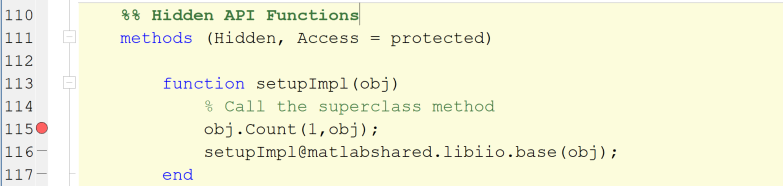

Similarly, as shown by the system object call sequence summary page linked previously, running the system object operator involves a call to the **stepImpl()** method. You will find this method in *TransceiverToolbox\+adi\+common\Rx.m*. Manually, add a breakpoint inside this method as before. 

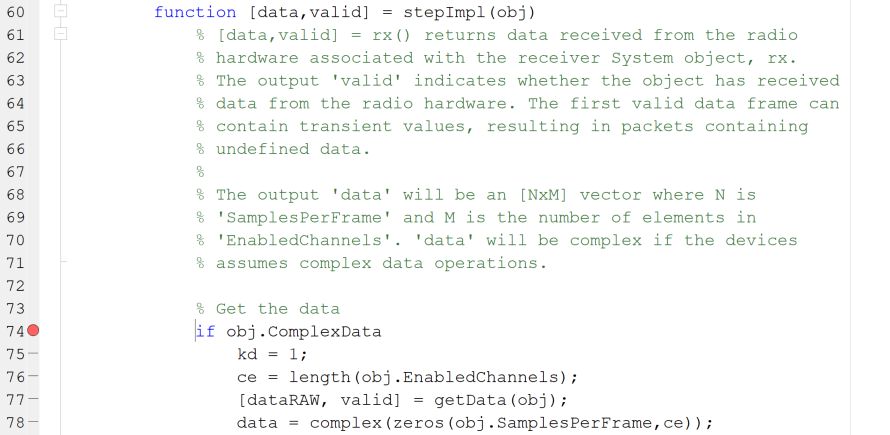

Next, navigate to *TransceiverToolbox\+adi\+AD9361\Rx.m* and add a breakpoint inside **setupInit()** method as shown below.

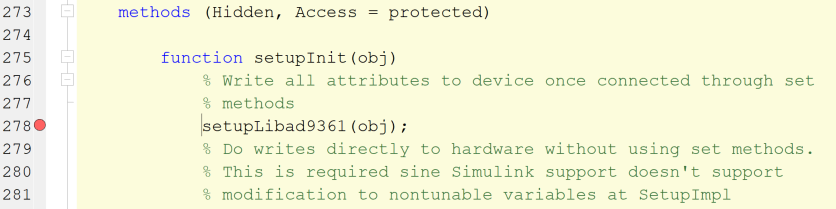

Now run the following code snippet shown below. If you are running the live script that generated this page, you may have noticed that this section can be run separately from the previous one. As you step through the **setupImpl()** method into the **Count()** method, you will notice that it keeps track of existing system objects if their state is needed by others. This is typically used for profile management between RX and TX variants of the same device. 

plutoRx = adi.Pluto.Rx('uri','ip:pluto.local');
y = plutoRx();

Furthermore, with the code execution paused inside **setupInit()** of *TransceiverToolbox\+adi\+AD9361\Rx.m*, you will notice by inspecting the code inside this method that it writes certain fundamental attributes to the device you are connected to as part of the **setupImpl()** step. Also, by running either the ***dbstack*** command or by observing the *Function Call Stack* dropdown menu, you can see the methods traversed during the setup process leading up to this breakpoint. As you step forward from this breakpoint, you may check by using the ***iio_attr*** utility that after each **setAttribute*()** call, the corresponding attribute has been written to the driver. The next stage in the setup process involves involves [enabling channels and creating buffers](https://wiki.analog.com/resources/tools-software/linux-software/libiio_internals#reading_and_writing), regarding which more details can be found in the link provided. 

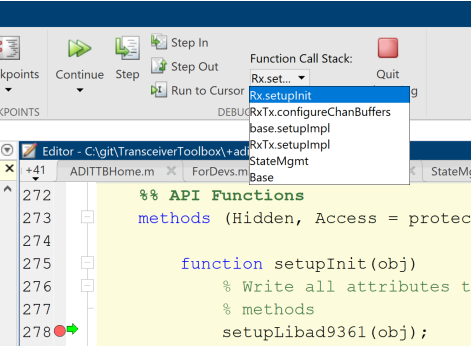

Eventually, when you decide to continue to the next breakpoint, you will find that the execution pauses inside the [**stepImpl()**](https://www.mathworks.com/help/matlab/ref/matlab.system.stepimpl.html) method in *TransceiverToolbox\+adi\+common\Rx.m,* which actually executes the process of capturing a buffer from the device and transforming it into a MATLAB vector. Subsequently, as you run the **plutoRx()** operator multiple times as shown below, you will notice that the subsequent buffer captures will only run the **stepImpl()** method since the system object has been setup already. Thus, state is being maintained from the first buffer capture until **release()** method is called. You will also observe that there is a noticeable delay when obtaining the first buffer capture compared to the second buffer capture. This is due to the fact that kernel buffers are setup on the first system object operator call and during subsequent calls, samples are available in the FIFO for transferring them into MATLAB. 

y = plutoRx();
y = plutoRx();
release(plutoRx);